% AAE 666 HW8 Exercise 5
% Tomoki Koike
close all; clear all; clc;

% Define arbitrary constants
g = 9.8;  % [m/s2]
l = 2;  % [m]
m = 1;  % [kg]
I = 10;  % [kg-m2]

% Define parameters
a = m*g*l/I;
b = 1/I;

% Uncertain parameter
kp = a/b + 1;
kd = 1;
K = [kp kd];

% Simulate and plot 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

res = sim('ex5');

t = res.tout;
q = res.q.signals.values;
qdot = res.qdot.signals.values;

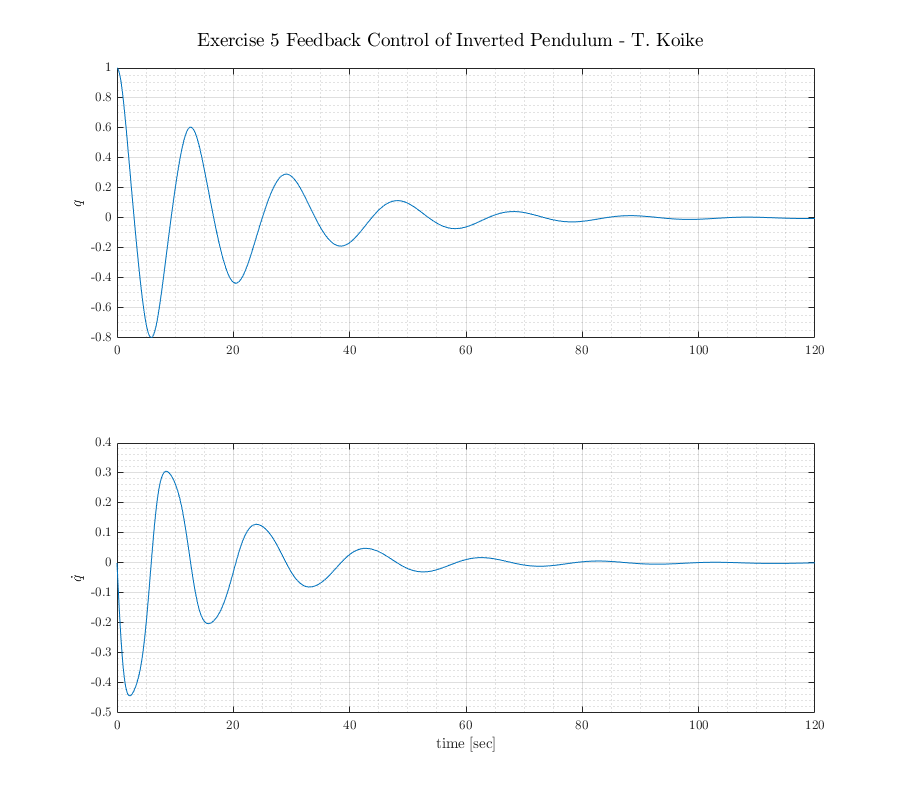

% - Plot 
fig = figure("Renderer","painters","Position",[60 60 900 800]);
    subplot(2,1,1)
    plot(t, q)
    grid on; grid minor; box on;
    ylabel('$q$')
    subplot(2,1,2)
    plot(t, qdot)
    grid on; grid minor; box on;
    ylabel('$\dot{q}$')
    xlabel('time [sec]')
    title_string = 'Exercise 5 Feedback Control of Inverted Pendulum - T. Koike';
    sgtitle(title_string)
saveas(fig, 'ex5_invPend.png')

% Save file as .m
matlab.internal.liveeditor.openAndConvert('aae666_hw9_p4.mlx', ...
    convertStringsToChars('aae666_hw9_p4.m'));